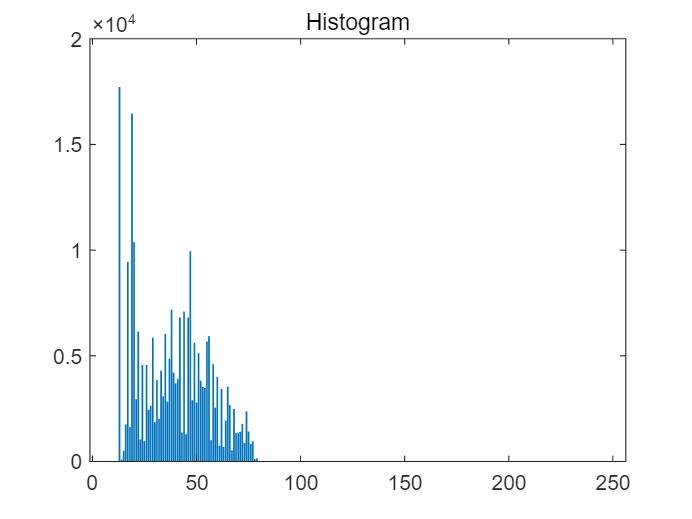

load Q3\original_img.mat;
source=imread("Q3\source.jpg");
target=imread("Q3\target.jpg");
[n,m]=size(original_img);
cnt=zeros(256,1);
bin=zeros(256,1);
for i=[1:256]
    bin(i,1)=i-1;
end
for i=[1:n]
    for j=[1:m]
        cnt(original_img(i,j)+1,1)=cnt(original_img(i,j)+1,1)+1;
    end
end
bar(bin,cnt);title("Histogram");

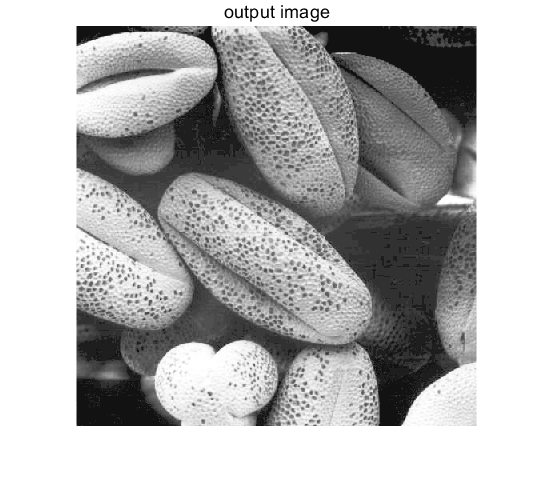


p=cnt/(n*m);
p=cumsum(p);
p=p*255;
p=round(p);
output=uint8(zeros(n,m));
for i=[1:n]
    for j=[1:m]
        output(i,j)=p(original_img(i,j)+1,1);
    end
end
imshow(output);title("output image");

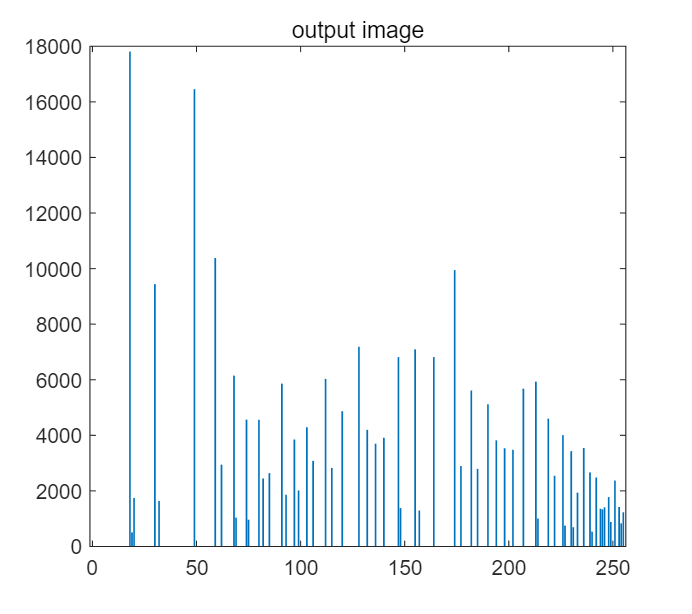

[counts,binLocations]=imhist(output);
bar(binLocations,counts);title("output image");

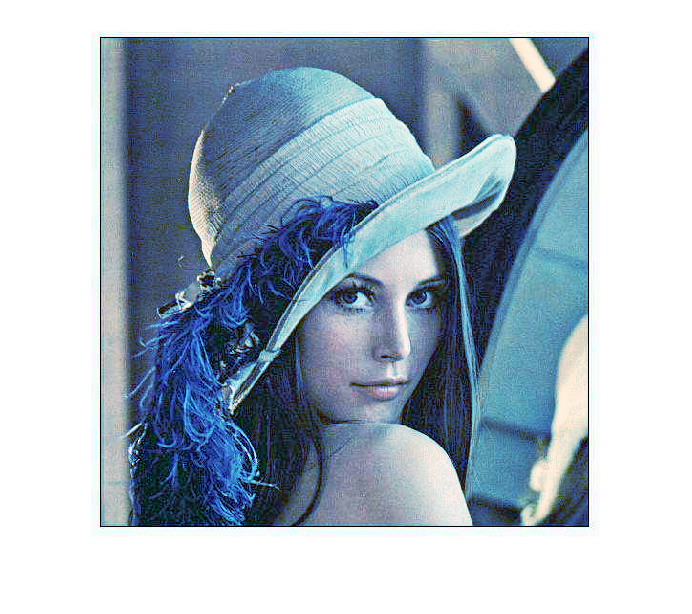


[source_n,source_m,dim]=size(source);
[target_n,target_m,dim]=size(target);
x=uint8(zeros(source_n,source_m,3));
for k=[1:3]
    source_x=source(:,:,k);%获取原图像k通道
    source_hist=imhist(source_x);%获取原图像k通道直方图
    target_x=target(:,:,k);%获取匹配图像k通道
    target_hist=imhist(target_x);%获取匹配图像k通道直方图
    %x(:,:,k)=histeq(source_x,target_hist);%R通道直方图匹配,系统自带,可惜不让用
    source_p=cumsum(source_hist)/(source_n*source_m);
    target_p=cumsum(target_hist)/(target_n*target_m);
    map=zeros(1,256);%从0到255分别的映射
    %help min
    for i=[1:256]
        [val,pos]=min(abs(source_p(i)-target_p));%找到target_p中与source(i)最接近的位置
        map(i)=pos-1;
    end
    x(:,:,k)=map(double(source_x)+1);
end
result=cat(3,x(:,:,1),x(:,:,2),x(:,:,3));
imshow(result);

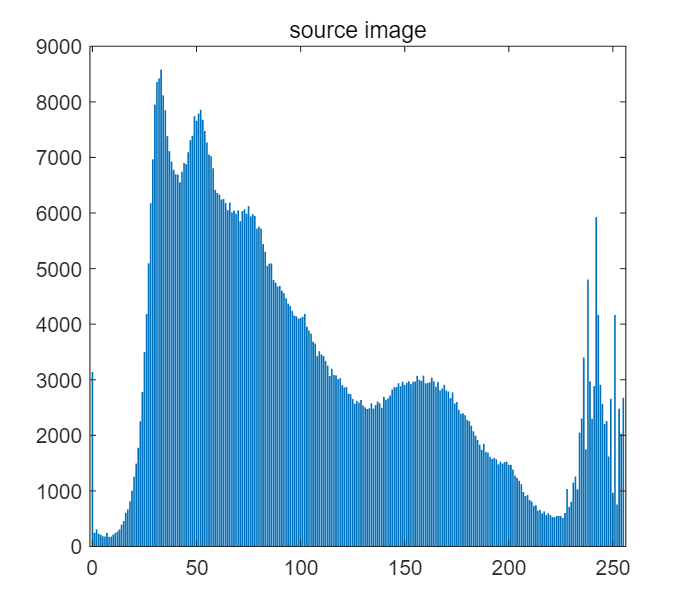


[counts,binLocations]=imhist(source);
bar(binLocations,counts);title("source image");

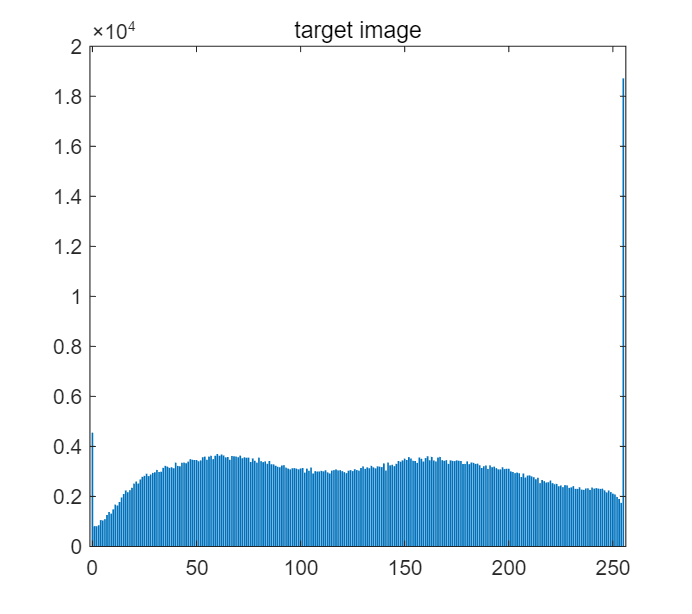

[counts,binLocations]=imhist(target);
bar(binLocations,counts);title("target image");

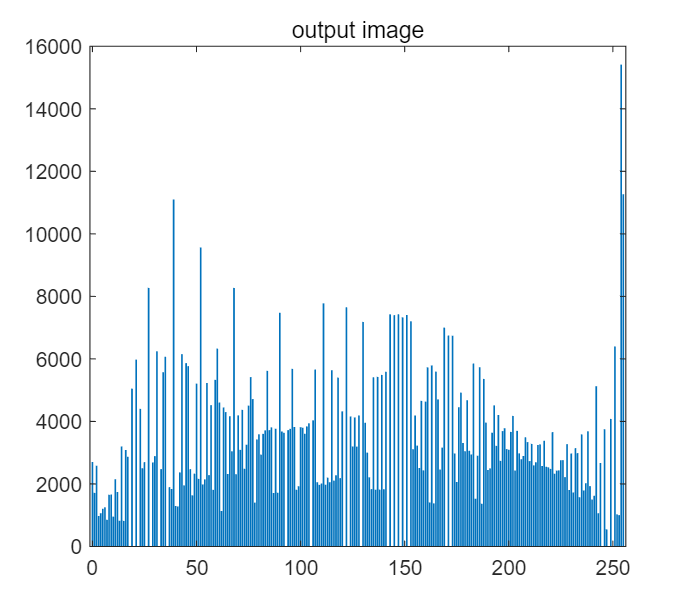

[counts,binLocations]=imhist(result);
bar(binLocations,counts);title("output image");